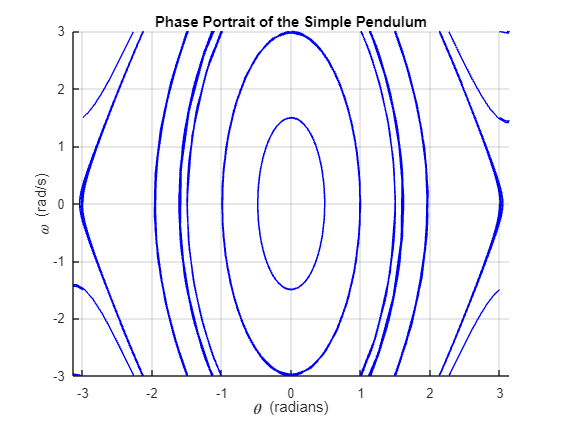


    % Constants for the simple pendulum
    g = 9.81; % acceleration due to gravity (m/s^2)
    L = 1.0;  % length of the pendulum (m)

    % Time span for the simulations
    t_span = [0 10];

    % Create a grid of initial conditions for theta and omega
    theta_vals = linspace(-3, 3, 5);
    omega_vals = linspace(-3, 3, 5);

    % Initialize figure
    figure;
    hold on;

    % Plot the phase portrait for each initial condition
    for theta0 = theta_vals
        for omega0 = omega_vals
            % Initial conditions
            y0 = [theta0 omega0];

            % Solve the ODE
            [t,y] = ode45(@(t,y) pendulum_ode(t, y, g, L), t_span, y0);

            % Plot the trajectory in the phase space
            plot(y(:,1), y(:,2), 'b');
        end
    end

    % Configure the plot
    xlabel('\theta (radians)');
    ylabel('\omega (rad/s)');
    title('Phase Portrait of the Simple Pendulum');
    xlim([-pi pi]);
    ylim([-3 3]);
    grid on;
    hold off;



% Function that defines the ODE of the simple pendulum

function dydt = pendulum_ode(t, y, g, L)
    dydt = zeros(2,1);
    dydt(1) = y(2); % theta_dot = omega
    dydt(2) = -(g/L) * sin(y(1)); % omega_dot = -g/L * sin(theta)
end
